# `调用函数`

`在上一章中，我们介绍了常见的数学运算函数，例如`abs, sin, round, log`等。这些函数可以直接应用到矩阵上，所表示的含义是：对矩阵中的每个元素分别运用这些数学运算函数，因此返回的结果也是一个矩阵。下面我们来举几个例子：`

x = randi(5,3,4)

x =      5     5     2     5
     5     4     3     1
     1     1     5     5


exp(x)

ans =   148.4132  148.4132    7.3891  148.4132
  148.4132   54.5982   20.0855    2.7183
    2.7183    2.7183  148.4132  148.4132


log(x)

ans =     1.6094    1.6094    0.6931    1.6094
    1.6094    1.3863    1.0986         0
         0         0    1.6094    1.6094


y = rand(4,3)  % 生成0-1之间均匀分布的随机数

y =     0.9572    0.4218    0.6557
    0.4854    0.9157    0.0357
    0.8003    0.7922    0.8491
    0.1419    0.9595    0.9340


round(y,2)  % 四舍五入保留两位小数

ans =     0.9600    0.4200    0.6600
    0.4900    0.9200    0.0400
    0.8000    0.7900    0.8500
    0.1400    0.9600    0.9300


x = randi(10,3)

x =      7     4     8
     8     7     1
     8     2     3


mod(x, 3)  % 计算x中各元素除以3的余数

ans =      1     1     2
     2     1     1
     2     2     0


`除了这些最基础的数学运算函数外，这一小节我们还要学习几个使用频率较高的函数，大家需要熟练掌握：`

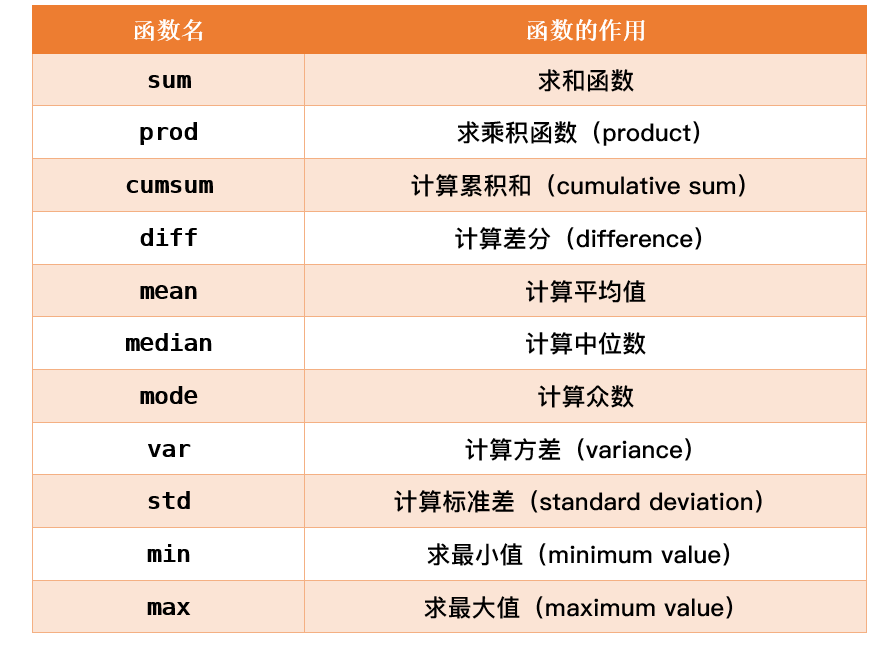

## sum ：`求和函数`

`（1）如果A是一个向量，则sum(A)可以计算A中所有元素的和。`

A = 1:100

A =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


sum(A)

ans = 5050

**（2）如果A是一个矩阵，则sum(A,dim)可以计算A沿维度 dim 中所有元素的和。**

**dim=1表示沿着行方向，即计算每一列的和。当dim=1时，sum(A,1)可以简写成sum(A)**

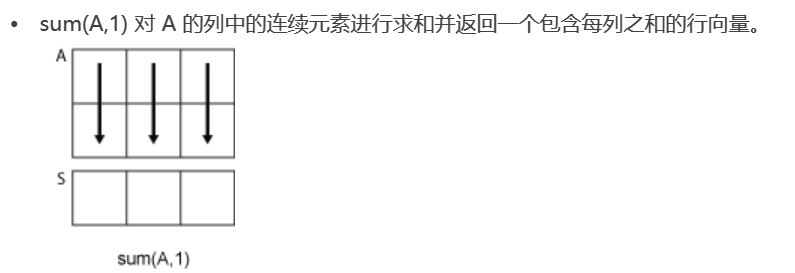

**dim=2表示沿着列方向，即计算每一行的和。**

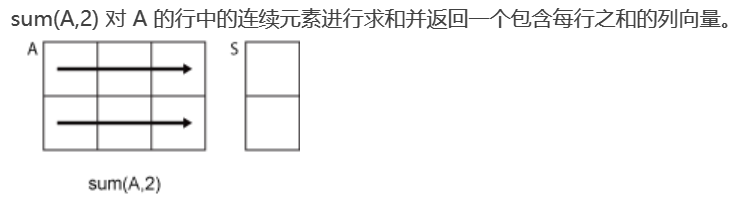

A = randi(10,3,4)

A =      4     8     7     6
     6     3     9     2
     3     6    10     2


sum(A,1)  % 计算每一列的和，返回行向量

ans =     13    17    26    10


sum(A)  % dim=1时可以不写

ans =     13    17    26    10


sum(A,2)  % 计算每一行的和，返回列向量

ans =     25
    20
    21


**（3）计算一个矩阵中所有元素的总和**

sum(sum(A))  % 计算每一列的和，返回一个行向量，然后再计算这个行向量的和

ans = 66

也可以使用下面这个方法：

A(:) % 把A按照列拼接成一个向量

ans =      4
     6
     3
     8
     3
     6
     7
     9
    10
     6


sum(A(:))

ans = 66

`补充：从`MATLAB2018b`版本开始，可以使用`sum(A,'all')`来计算所有元素的和。`

% sum(A,'all')

**（4）指定如何处理 NaN 值**

NaN（Not a Number）`指不定值或缺失值。例如计算`0/0 `或` 0*Inf`会返回`NaN

默认情况下，如果计算时有一个元素为NaN，那么最终会返回NaN；

我们可以在最后加一个输入参数: 'omitnan', 这样就会忽略NaN

A = [1 5 NaN 10];  % 向量中存在NaN
sum(A) 

ans = NaN

sum(A, "omitnaN") % 忽略NaN值

ans = 16

A = [5 3 -8   4
1 5 NaN 10; 
3 6 18  9]; % 矩阵中存在NaN
sum(A) % 计算每一列的和

ans =      9    14   NaN    23


sum(A, 'omitnan')  % 忽略NaN值

ans =      9    14    10    23


sum(A, 2)  % 计算每一行的和

ans =      4
   NaN
    36


% 忽略NaN值
sum(A, 2, 'omitnan')

ans =      4
    16
    36


## prod ：求乘积函数`（`**product**`）`

`prod``函数的用法和``sum``函数的用法相同，它是用来计算乘积的，我们直接来看例子。`

v = [2,4,5,1,10];  % 向量
prod(v)  % 直接向量中所有元素的乘积 

ans = 400

v = 1:10; 
prod(v)  % 计算10的阶乘

ans = 3628800

% 熟练的话可以直接写成prod(1:10)
% 下面看矩阵的例子
A = randi(10,3,4)

A =      3     9     4     7
     9     3     2     5
     3    10     3     4


prod(A)  % 计算每列的乘积

ans =     81   270    24   140


% 也可以写成prod(A, 1)
prod(A,2)  % 计算每行的乘积

ans =    756
   270
   360


v = [2,4,NaN,1,10];  % 有NaN值
prod(v)

ans = NaN

% 如果计算时忽略NaN值，可以在最后面加上'omitnan'参数
prod(v, 'omitnan')

ans = 80

A = [5 3 -8   4
1 5 NaN 10; 
3 6 18  9];  % 矩阵中存在NaN值
prod(A)  % 计算每一列的乘积

ans =     15    90   NaN   360


prod(A, 'omitnan')  % 忽略NaN值

ans =     15    90  -144   360


% 忽略NaN值计算每一行的乘积
prod(A, 2, 'omitnan')

ans =         -480
          50
        2916


## `cumsum ``：计算累积和（`**cumulative sum**`）`

`（`1`）如果`A`是一个向量，则`cumsum(A)`可以计算向量`A`的累积和（累加值）。`

A = [1 5 3 4 -5 0 8];
cumsum(A)

ans =      1     6     9    13     8     8    16


（2）如果A是一个矩阵，则cumsum(A,dim)可以计算A沿维度 dim 中所有元素的累积和，具体的使用方法和sum函数类似。

A = randi(10,3,4)

A =      9    10     8     1
     6     3     4     1
     6     8     6     6


% 计算每一列的累积和
cumsum(A)  % 或者写成cumsum(A,1)

ans =      9    10     8     1
    15    13    12     2
    21    21    18     8


% 计算每一行的累积和
cumsum(A,2)

ans =      9    19    27    28
     6     9    13    14
     6    14    20    26


（3）也可以在最后加一个输入参数: 'omitnan', 这样计算时会忽略NaN。

A = [5 3 -8   4
1 5 NaN 10; 
3 6 18  9];
cumsum(A)  % 计算每一列的累积和

ans =      5     3    -8     4
     6     8   NaN    14
     9    14   NaN    23


% 忽略NaN值计算每一列的累积和
cumsum(A,'omitnan')

ans =      5     3    -8     4
     6     8    -8    14
     9    14    10    23


cumsum(A, 2)  % 计算每一行的累积和

ans =      5     8     0     4
     1     6   NaN   NaN
     3     9    27    36


% 忽略NaN值计算每一行的累积和
cumsum(A, 2, 'omitnan')

ans =      5     8     0     4
     1     6     6    16
     3     9    27    36


## `diff ``：计算差分（`**difference**`）`

`差分运算在和时间相关的数据中用的比较多。在原始序列中用下一个数值减去上一个数值可以得到一个新的序列，这个过程就是一阶差分；在一阶差分结果的基础上再进行一次一阶差分，就是二阶差分，举个例子，下表是清风老师`8`年来的体重变化，我们可以计算一阶差分和二阶差分的结果``：`

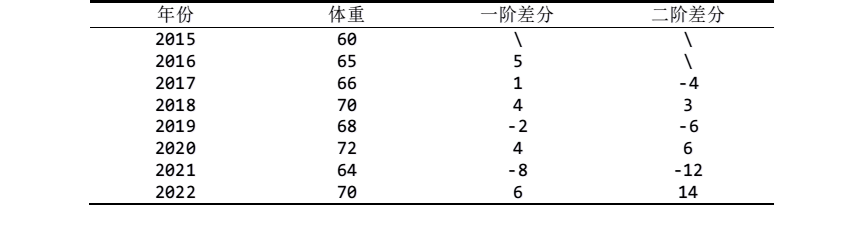

MATLAB`中计算差分的函数是`diff`，我们可以使用`diff(A,n)`命令计算向量`A`的`n`阶差分，当`n`等于`1`时，可以直接写成`diff(A).

w = [60 65 66 70 68 72 64 70];
diff(w)  % 1阶差分, diff(w,1)

ans =      5     1     4    -2     4    -8     6


diff(w,2)  % 2阶差分

ans =     -4     3    -6     6   -12    14


diff(w,3)  % 3阶差分

ans =      7    -9    12   -18    26


diff`函数也可以用在矩阵上面：`diff(A,n,dim)`表示沿矩阵`A`的维度`dim`方向上计算差分，当`dim=1`时沿着行方向计算，即得到每列的`n`阶差分；当`dim=2`时沿着列方向计算，即得到每行的`n`阶差分。类似的，`dim=1`时，`diff(A,n,1)`也可以简写成`diff(A,n).

A = randi(10,3,4)

A =      7     5     2     5
     4     1     2     1
     6     3     3    10


% 计算每列的1阶差分
diff(A)  % 也可写成diff(A,1)或diff(A,1,1)

ans =     -3    -4     0    -4
     2     2     1     9


% 计算每列的2阶差分
diff(A,2) % 也可写成diff(A,2,1)  

ans =      5     6     1    13


% 计算每行的1阶差分
diff(A,1,2) 

ans =     -2    -3     3
    -3     1    -1
    -3     0     7


% 计算每行的2阶差分
diff(A,2,2)

ans =     -1     6
     4    -2
     3     7


`注意，`diff`函数``不支持使用`'omitnan'`参数来忽略向量或者矩阵中的`NaN`值。`

w = [60 65 NaN 70 68 72 64 70];
diff(w)  

ans =      5   NaN   NaN    -2     4    -8     6


% % 尝试使用'omitnan'参数
% 报错：错误使用 diff；差分阶数 N 必须为正整数标量。
% diff(w, 'omitnan')  

% % 加上差分阶数
% 报错：错误使用 diff；维度参数必须是处于索引范围内的正整数标量。
% diff(w, 1, 'omitnan')

% % 加上维度
% 报错：错误使用 diff；输入参数太多。
% diff(w, 1, 2,'omitnan')

## mean : 计算平均值`（`**average/mean value**`）`

假设有一个向量$y=\left\lbrack \begin{array}{cccc}
y_1  & y_2  & \cdots  & y_n 
\end{array}\right\rbrack ,\textrm{向量y有n个元素，那么它的平均值：}\bar{\mathrm{y}} \;=\;\frac{\sum_{i=1}^n y_i }{n}$.

`（`1`）如果`A`是一个向量，则`mean(A)`可以计算向量`A`的平均值。`

y = [1 3 5 7 9];
mean(y)

ans = 5

（2）`如果`A`是一个矩阵，则`mean(A,dim)`可以计算`A`沿维度`dim`中所有元素的平均值。`

`    当`dim=1`时沿着行方向计算，即得到每列的平均值；`

`    当`dim=2`时沿着列方向计算，即得到每行的平均值。`

`    类似的，`dim=1`时，`mean(A,1)`也可以简写成`mean(A).

A = randi(10,3,4)

A =      2     6     4     1
    10     1     9     2
    10     3     1     7


mean(A)

ans =     7.3333    3.3333    4.6667    3.3333


mean(A,1)

ans =     7.3333    3.3333    4.6667    3.3333


mean(A,2)

ans =     3.2500
    5.5000
    5.2500


（3）也可以在最后加一个输入参数: 'omitnan', 这样计算时会忽略NaN。

A = [5 3 -8   4
1 5 NaN 10; 
3 6 18  9];
mean(A)  % 计算每一列的平均值

ans =     3.0000    4.6667       NaN    7.6667


% 忽略NaN值计算每一列的平均值
mean(A,'omitnan')  

ans =     3.0000    4.6667    5.0000    7.6667


% 也可以写成mean(A,1,'omitnan')
mean(A, 2)  % 计算每一行的平均值

ans =      1
   NaN
     9


% 忽略NaN值计算每一行的平均值
mean(A, 2, 'omitnan')

ans =     1.0000
    5.3333
    9.0000


## median ：计算中位数`（`**median**`）`

`中位数又称中值，我们将数据按从小到大的顺序排列，在排列后的数据中居于中间位置的数就是中位数。`

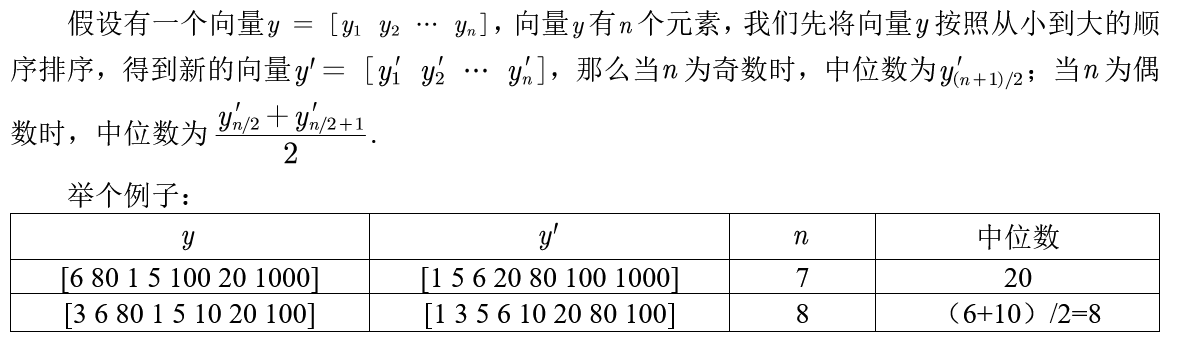

`在`MATLAB`中，`median`函数可以用来计算中位数，它的使用方法和`mean`函数类似。`

y = [6 80 1 5 100 20 1000];
median(y)

ans = 20

A = [5 3 -8   4
1 5 NaN 10; 
3 6 18  9];
median(A)  % 计算每一列的中位数

ans =      3     5   NaN     9


% 忽略NaN计算每一列的中位数
median(A,'omitnan')

ans =      3     5     5     9


% 也可以写成median(A,1,'omitnan')
% 忽略NaN计算每一行的中位数
median(A, 2, 'omitnan')

ans =     3.5000
    5.0000
    7.5000


median(A(:), 'omitnan')  % 整个矩阵的中位数

ans = 5

## `mode ``：计算众数（`**mode**`）`

`众数是指一组数据中出现次数最多的数。一组数据可以有多个众数，例如向量`[1 3 -1 2 1 3]`中，`1`和`3`都出现了两次，它们都是这组数据中的众数。`

MATLAB`中可以使用`mode`函数计算数据的众数，调用方法也和`mean`函数类似，但是`mode`函数可以有多个返回值。`

`以计算向量`A`的众数为例，直接调用`mode(A)`会返回`A`中出现次数最多的值。如果有多个值以相同的次数出现，`mode`函数将返回其中最小的值。`

A = [2 3 -1 2 1 3];
mode(A)  

ans = 2

`如果`A`是一个矩阵，则`mode(A,1)`或者`mode(A)`可以沿着行方向进行计算，得到每一列的众数；`mode(A,2)`可以沿着列方向进行计算，得到每一行的众数，这里的`1`和`2`表示维度`dim`。`

A = randi(5,6,8)

A =      5     1     2     2     2     1     4     4
     4     3     4     3     3     3     4     3
     2     2     2     1     1     1     1     5
     1     2     5     5     3     3     1     4
     3     3     5     5     2     3     2     5
     3     2     4     5     1     4     3     3


mode(A)

ans =      3     2     2     5     1     3     1     3


mode(A,2)

ans =      2
     3
     1
     1
     3
     3


`注意：使用`mode`函数计算众数时会自动忽略`NaN`值，我们不能额外添加`'omitnan'`参数，否则会报错。`

A = [2 3 -1 NaN 1 NaN NaN 3];
mode(A)

ans = 3

% 报错：错误使用 mode (第 97 行)
% 维度参数必须为正整数标量、由唯一正整数组成的向量或 'all'。
% mode(A, 'omitnan')

% 错误使用 mode
% 输入参数太多。
% mode(A, 2, 'omitnan')

`现在我们来看`mode`函数有两个返回值的例子，如果`A`是一个向量，`[M,F] = mode(A)`得到的`M`表示向量`A`的众数，`F`表示众数`M`在向量`A`中出现的次数。`

A = [-1 2 0 8 -1 0 2 1 8 0 8];
[M, F] =mode(A)

M = 0

F = 3

面这个例子中，有两个众数，分别是0和8，它们出现的次数都是3次，此时MATLAB会返回最小的那个数作为众数。有同学会想，MATLAB能不能把这些众数都输出呢？

当然可以，我们需要用到mode函数的第三个返回值：[M,F,C] = mode(A), 这里的C是一个元胞数组，元胞数组里面有一个列向量，列向量中的每个元素都是向量A的众数。（注意，元胞数组是使用大括号{}括起来的，元胞数组(cell array)里面的元素可以包含不同的数据类型，例如标量、向量、矩阵、字符串等，后面章节中我们会专门讲解元胞数组的用法）

A = [-1 2 0 8 -1 0 2 1 8 0 8];
[M, F, C] =mode(A)

M = 0

F = 3

C = 1×1 cell 数组
    {2×1 double}

`变量`C`就是元胞数组，它的大小为`1×1`，即一行一列，因此里面只有一个元素，这个元素是一个`2`行`1`列的列向量。我们可以使用大括号索引的方式来提取元胞数组中的元素：`

C{1}

ans =      0
     8


`命令`C{1}`可以提取出元胞数组`C`中的第一个元素：列向量`[0; 8]`。这个列向量中的元素`0`和`8`都是向量`A`的众数。`

`以上是`A`为向量时的情况，如果`A`是一个矩阵，`mode`函数也可以有两个返回值或三个返回值，后两个返回值代表的含义与`A`为向量时类似。我们直接看下面的例子：` 

A =  [3 3 1 4; 
     0 0 1 1;
     0 1 6 4;
     1 5 6 8];
[M, F, C] = mode(A) % 计算每一列的众数

M =      0     0     1     4


F =      2     1     2     2


C = 1×4 cell 数组
    {[0]}    {4×1 double}    {2×1 double}    {[4]}

M`是一个包含四个元素的行向量，里面的第`k`个元素表示第`k`列的众数，例如第`1`列的众数为`0`；如果有多个众数，那么会返回最小的那个值，因此第`2`列返回的众数为`0`。`

F`也是一个包含四个元素的行向量，它表示`M`中的各个众数在其所在列中出现的次数，例如第`1`列的众数`0`在第`1`列出现了`2`次。`

C`是一个大小为`1×4`的元胞数组，里面的第`k`个元素表示第`k`列的所有众数。从元胞数组`C`的结果来看，第一个和第四个元素分别为`0`和`4`，这说明第`1`列和第`4`列都只有一个众数，分别是`0`和`4`；`C`中第二个元素是一个`4`行`1`列的列向量，这说明第`2`列有四个众数；`C`中第三个元素是一个`2`行`1`列的列向量，这说明第`3`列有两个众数。`

`我们可以使用大括号索引提取`C`中的每个元素：`

C{1}

ans = 0

C{2}

ans =      0
     1
     3
     5


C{3}

ans =      1
     6


C{4}

ans = 4

[M, F, C] = mode(A, 2)  %计算A矩阵每一行的众数

M =      3
     0
     0
     1


F =      2
     2
     1
     1


C = 4×1 cell 数组
    {[       3]}
    {2×1 double}
    {4×1 double}
    {4×1 double}

C{1}

ans = 3

C{2}

ans =      0
     1


C{3}

ans =      0
     1
     4
     6


C{4}

ans =      1
     5
     6
     8


## `var ：计算方差`**(variance)**

**MATLAB**`中使用`**var**`函数计算方差：`

`（`1`）如果`A`是一个向量，那么`var(A, w)`可以计算`A`的方差，当`w=0`时，表示计算样本方差，`w=1`时表示计算总体方差，另外，`var(A, 0)`也可以直接简写为`var(A)`。`

`（`2`）如果`A`是一个矩阵，则`var(A, w, dim)`可以计算矩阵`A`沿维度`dim`上的方差。`

- dim = 1`时表示沿着行方向进行计算，即得到每一列的方差；`

- dim = 2`时表示沿着列方向进行计算，即得到每一行的方差。`

`当`dim`为`1`时，`var(A, w, 1)`可以简写为`var(A,w)`；若`w`为`0`，则可以进一步简写为`var(A)`，即默认情况下`MATLAB`会沿行方向计算得到每一列的样本方差。`

`（3）如果数据中存在`NaN`值，可以在`var`函数的最后加上`'omitnan'`参数来忽略`NaN.

v = [6 8 10 12 14];  
var(v)  % 样本方差，等价于var(v,0)

ans = 10

var(v,1)  % 总体方差

ans = 8

% 下面看矩阵的例子
A = randi(10,4,5)

A =      5     2     8     7    10
     4     5     8     2     4
     8     5     3     2     6
     8     7     7     5     3


var(A)  % 每一列的样本方差

ans =     4.2500    4.2500    5.6667    6.0000    9.5833


% 也可以写成var(A,0)或者var(A,0,1) 
var(A,0,2)  % 每一行的样本方差

ans =     9.3000
    4.8000
    5.7000
    4.0000


A = [9  7    10  10  NaN;
10  NaN 10  5   10;
2   3    2   9   8;
10  6   10    2  10];  
% 矩阵中存在NaN值
var(A, 0, 2)  % 计算每一行的样本方差

ans =        NaN
       NaN
   11.7000
   12.8000


% 忽略NaN值计算每一行的样本方差
var(A, 0, 2, 'omitnan')  

ans =     2.0000
    6.2500
   11.7000
   12.8000


## `std ：计算标准差（standard deviation）`

`标准差是方差的算术平方根，它也是用来反应数据离散程度的一个统计量。那么问题来了，既然有了方差为什么还需要标准差呢？这是因为方差和数据原本的量纲（即单位）是不一致的，对方差的计算公式进行量纲分析容易看出，方差的量纲是原始数据量纲的平方，因此对方差开根号，得到的标准差的量纲和原始数据的量纲一致。`

`在`MATLAB`中，我们可以使用`std`函数计算样本标准差和总体标准差，它和`var`函数的使用方法完全相同。`

v = [6 8 10 12 14];  
std(v)  % 样本标准差，等价于std(v,0)

ans = 3.1623

std(v,1)  % 总体标准差

ans = 2.8284

% 下面看矩阵的例子
A = randi(10,4,5)

A =      8     9     2     9     2
     3    10     3     3     3
     6     6     9    10     7
     7     2     3     4     5


std(A)  % 每一列的样本标准差

ans =     2.1602    3.5940    3.2016    3.5119    2.2174


% 也可以写成std(A,0)或者std(A,0,1) 
std(A,0,2)  % 每一行的样本标准差

ans =     3.6742
    3.1305
    1.8166
    1.9235


A = [9  7    10  10  NaN;
10  NaN 10  5   10;
2   3    2   9   8;
10  6   10    2  10];  
% 矩阵中存在NaN值
std(A, 0, 2)  % 计算每一行的样本标准差

ans =        NaN
       NaN
    3.4205
    3.5777


% 忽略NaN值计算每一行的样本标准差
std(A, 0, 2, 'omitnan') 

ans =     1.4142
    2.5000
    3.4205
    3.5777


## `min : 求最小值（minimum）`

min`函数主要有两种用法：`

`用法一：求两个矩阵对应位置元素的最小值`**:**  ***min(A,B)***`。`

A = randi(10,4,3)

A =      3     4     7
     3     8     4
     7     7    10
     9     1     1


B = randi(10,4,3)

B =      5     4     2
     5     8     8
     5     5     5
     8     1     2


min(A,B)

ans =      3     4     2
     3     8     4
     5     5     5
     8     1     1


`矩阵`A`和矩阵`B`的大小可以不一样，只要保证矩阵`A`和矩阵`B`具有兼容的大小就能够计算，`MATLAB`矩阵运算中支持的兼容模式会在“`3.1.2`算术运算”这一小节中详细介绍。`

`下面再举两个例子：表中第三列是运行`min(A, B)`后返回的结果。`

A = randi(10,4,3)

A =      4     3     2
     7    10     3
     2     3     1
     8     8     6


B = 5;  % 例如B可以是一个标量（常数）
min(A,B)

ans =      4     3     2
     5     5     3
     2     3     1
     5     5     5


B = [4 5 6];
min(A,B)

ans =      4     3     2
     4     5     3
     2     3     1
     4     5     6


`用法二：求向量或者矩阵中的最小值，可以指定沿什么维度计算并返回索引。`

`具体用法有以下三种：`

`（`1`）如果`A`是向量，则`min(A)`返回`A`中的最小值。如果`A`中有复数，则比较的是复数的模长。`

A = [5 6 7 3 5 3 10];
min(A)

ans = 3

B = [4.5  3+4i  6];
min(B)  

ans = 4.5000

`（`2`）如果`A`是矩阵，则`min(A, [ ], 1)`沿着`A`的行方向求每一列的最小值，也可以简写为`min(A)`；`min(A, [ ], 2)`沿着`A`的列方向求每一行的最小值。这里的`1`和`2`表示矩阵的维度（`dim`）。`

A = randi(10,3,4)

A =      7     7     7     8
     6     7    10     3
     5     7     3     2


min(A,[ ],1)  % 求每一列的最小值

ans =      5     7     3     2


min(A)    % 求每一列的最小值

ans =      5     7     3     2


min(A,[ ],2)  % 求每一行的最小值

ans =      7
     3
     2


`有同学可能会问`: `为什么中间要加一个空向量`[ ]? `如果不加的话，就是将`A`中每个元素和`1`或者`2`比较大小，并返回较小值。`

min(A, 1)

ans =      1     1     1     1
     1     1     1     1
     1     1     1     1


min(A, 2)

ans =      2     2     2     2
     2     2     2     2
     2     2     2     2


`（`3`）在求向量或矩阵的最小值时，`min`函数可以有两个返回值：`[m, ind] = min(A). `第一个返回值`m`是我们要求的最小值，`ind`是最小值在所在维度上的索引。如果最小元素出现多次，则` ind`是最小值第一次出现位置的索引。`

% 向量的例子
A = [5 6 7 3 5 3 10];
[min_A , ind] = min(A)

min_A = 3

ind = 4

% 矩阵的例子
A = [ 7  9  2  8
1  5  1  3
6  5  8  2];
[min_A , ind] = min(A,[ ],2)   % 求每一行的最小值并返回索引

min_A =      2
     1
     2


ind =      3
     1
     4


[min_A , ind] = min(A)   % 求每一列的最小值并返回索引

min_A =      1     5     1     2


ind =      2     2     2     3


求出整个矩阵的最小值

A = randi(100,3,4)

A =     61    67    67    84
    46    78    42    26
    46    36    85    62


min(A(:))

ans = 26

`上面我们介绍了`min`函数的两种用法，如果向量或者矩阵中存在`NaN`值，`min`函数会自动忽略，大家不需要单独对`NaN`值进行处理。`

% 存在缺失值的例子
A = [5 6 7 NaN 5 3 10];
[min_A , ind] = min(A)

min_A = 3

ind = 6

% 求x和y对应元素的最小值
x = [1  NaN  3   5   2  NaN  1];
y = [2   5   4  NaN  2  NaN  9];
min(x, y)

ans =      1     5     3     5     2   NaN     1


% 求两个矩阵对应位置元素的最小值时，min函数只能有一个返回值！
% 报错：错误使用 min
% 有两个输入数组时，不支持指定两个输出参量。
% [min_xy, ind] = min(x, y)

## `max :``求最大值（``maximum``）`

max`函数和`min`函数的用法相同，它是用来求最大值的函数。`

A = [ 2     6    10
     6     7     5
     5     3     7
     2     6     5 ];	
B = [ 1     1     6
     3     6     9
     9     4     9
     4     8     2 ];
max(A,B)

ans =      2     6    10
     6     7     9
     9     4     9
     4     8     5


A = [5 6 10 7 3 5 3 10];
% 计算向量A的最大值并返回其索引
[max_A, ind] = max(A)

max_A = 10

ind = 3

A = randi(10,3,4)

A =      6    10     2     5
     8     3     1     4
     6     2     5     8


max(A, [ ], 1)  % 求每一列的最大值

ans =      8    10     5     8


max(A)    % 求每一列的最大值

ans =      8    10     5     8


max(A, [ ], 2)  % 求每一行的最大值

ans =     10
     8
     8


max(A, 2) % 返回每个元素和2相比的较大值

ans =      6    10     2     5
     8     3     2     4
     6     2     5     8


[max_A , ind] = max(A,[ ],2)   % 求每一行的最大值并返回索引

max_A =     10
     8
     8


ind =      2
     1
     4



[max_A , ind] = max(A)   % 求每一列的最大值并返回索引

max_A =      8    10     5     8


ind =      2     1     3     3



% 存在缺失值的例子
A = [5 6 7 NaN 5 3 10 5];
[max_A , ind] = max(A)

max_A = 10

ind = 7

## `拓展三个新函数：mink、maxk和topkrows`

## `mink :``求前``k``个最小值`

## `（这个函数在`**2017b**`版本中才推出）`

 mink`是用来求出前`k`个最小值的函数，它的使用方法类似于我们之前学的一些函数，例如`sum`和`mean`函数。`

[https://ww2.mathworks.cn/help/matlab/ref/mink.html](https://ww2.mathworks.cn/help/matlab/ref/mink.html)

`（`1`）如果`A`是一个向量，则`mink(A,k)`可以计算向量`A`的前`k`个最小值。`

（2）`如果`A`是一个矩阵，则`mink(A,k,dim)`可以计算`A`沿维度`dim的`前`k`个最小值。`

`    当`dim=1`时沿着行方向计算，即得到每列的前`k`个最小值；`

`    当`dim=2`时沿着列方向计算，即得到每行的前`k`个最小值。`

`    类似的，`dim=1`时，`mink(A,k,1)`也可以简写成`mink(A,k).

A = [1,5,0,4,9,9,3,5,8];
mink(A,3)

ans =      0     1     3


如果你是老版本的MATLAB，你怎么求出向量的前k个最小值？

可以先排序，再取出前k个元素。

sortA = sort(A);
sortA(1:3)

ans =      0     1     3


如果是矩阵：

A = randi(10,5,4)

A =      1     4     5     2
     8     8     1     9
     3     4     4     5
     5     7     5     9
     7     8     3     4


mink(A,3)  % 等价于mink(A,3,1)

ans =      1     4     1     2
     3     4     3     4
     5     7     4     5


老版本可以使用：

sortA = sort(A);
sortA(1:3,:)

ans =      1     4     1     2
     3     4     3     4
     5     7     4     5


mink(A,3,2)

ans =      1     2     4
     1     8     8
     3     4     4
     5     5     7
     3     4     7


sortA = sort(A,2);
sortA(:,1:3)

ans =      1     2     4
     1     8     8
     3     4     4
     5     5     7
     3     4     7


## `maxk :求前``k``个最大值`

## `（这个函数在`**2017b**`版本中才推出）`

 使用方法和mink类似

A = [1,5,0,4,9,9,3,5,8];
maxk(A,3)

ans =      9     9     8


如果你是老版本的MATLAB，你怎么求出向量的前k个最大值？

sortA = sort(A,'descend');
sortA(1:3)

ans =      9     9     8


## `topkrows :返回矩阵按照排序顺序的前若干行`

[https://ww2.mathworks.cn/help/matlab/ref/double.topkrows.html](https://ww2.mathworks.cn/help/matlab/ref/double.topkrows.html)

`这个函数的用法和上一节介绍的`sortrows`函数类似，`sortrows`函数基于某一列对整个矩阵进行排序，而`topkrows`函数则只返回排序后的前`k`行（默认是降序排列）。`

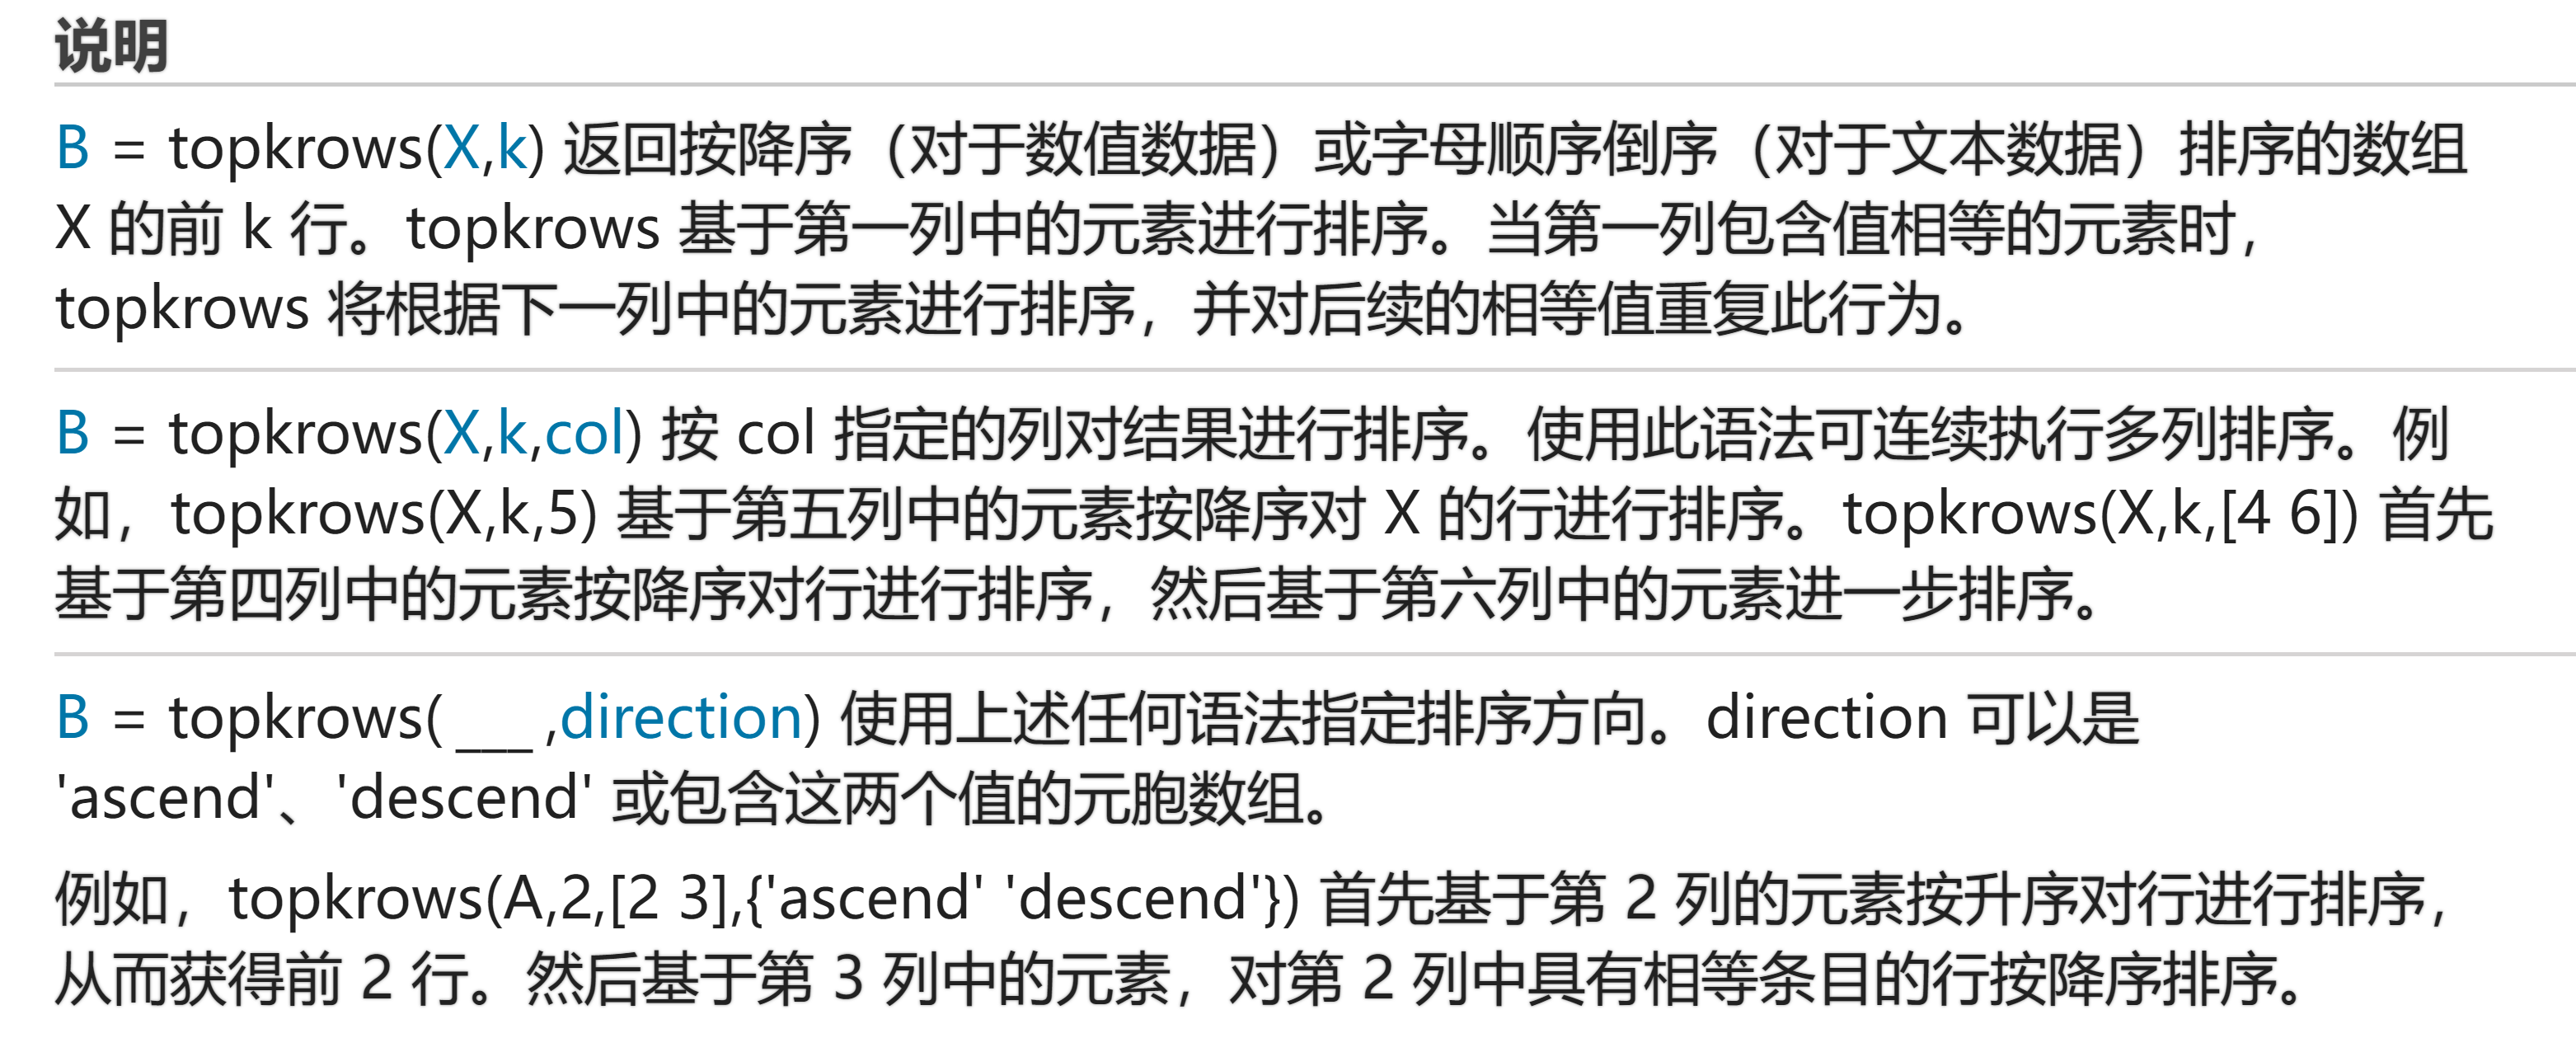

`注意：从MATLAB`**2017b**`版本后才可以使用这个函数对普通矩阵进行排序。`

x = randi(10,10,4)

x =      8     7     3     5
     6     6     7     2
     8     8     5     2
     3     4     2     8
     8     3     8     3
    10     1     2     7
     9     8     3    10
     1     3     3     5
     4     4     6     7
     4     6     1     8


 先基于第一列排序，第一列相同时基于第二列排序，第二列相同时基于第三列排序，依次类推，返回排序结果的前三行（默认是降序）

topkrows(x,3) 

ans =     10     1     2     7
     9     8     3    10
     8     8     5     2


等价于：

sx = sortrows(x,'descend');
sx(1:3,:)

ans =     10     1     2     7
     9     8     3    10
     8     8     5     2


基于第二列排序，并返回排序结果的前四行（默认是降序）

topkrows(x,4,2)  

ans =      8     8     5     2
     9     8     3    10
     8     7     3     5
     6     6     7     2


等价于：

sx = sortrows(x,2,'descend');
sx(1:4,:)

ans =      8     8     5     2
     9     8     3    10
     8     7     3     5
     6     6     7     2


再来看一个升序的例子

x = randi(10,10,4)

x =      5     3     2     2
     7     1     2     2
     2     7     1     1
    10     5     1     2
     2     5     5     2
     3     7     7     2
     8     1     8     4
     5     4     6     4
     8     8     2     3
     4     7     7     3


先基于第二列排序，第二列相同时再基于第四列排序，都相同则按照出现的先后顺序排序（顺序为升序），输出结果的前三行。

topkrows(x,3,[2,4],'ascend') % 返回前3行，改成升序

ans =      7     1     2     2
     8     1     8     4
     5     3     2     2


等价于：

sx = sortrows(x,[2,4]);
sx(1:3,:)

ans =      7     1     2     2
     8     1     8     4
     5     3     2     2


先基于第3列升序，第3列相同时再基于第2列降序，如果第2第3列都相同则按照出现的先后顺序排序，并返回结果的前4行。

topkrows(x,4,[3,2],{'ascend','descend'})

ans =      2     7     1     1
    10     5     1     2
     8     8     2     3
     5     3     2     2


等价于：

sx = sortrows(x,[3,2],{'ascend','descend'});
sx(1:4,:)

ans =      2     7     1     1
    10     5     1     2
     8     8     2     3
     5     3     2     2


**新版本的功能：以sum函数为例**

**R2018b: **对多个维度执行运算

一次对输入数组的多个维度执行运算。指定一个由运算维度组成的向量，或指定 "all" 选项以对所有数组维度执行运算。

a = randi(10,3,4)

a =      9    10     3    10
    10     7     6     2
     2     1    10    10


sum(a,"all")  % 双引号表示字符串

ans = 80

sum(a,'all')  % 单引号表示字符向量

ans = 80

sum(a,[1,2])

ans = 80

sum(sum(a))

ans = 80

sum(a(:))

ans = 80

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)